% List of data folders for each sample
dataFolders = {'sample4-3tests', 'sample5-3tests', 'sample6-3tests', 'sample7-3tests'};

% Preallocate result arrays
allAvgForceStds = zeros(1, 4);
allAvgDistanceStds = zeros(1, 4);

for n = 1:4
    dataFolder = dataFolders{n};
    files = dir(fullfile(dataFolder, '*.csv'));

    % Store residual stds for this sample
    forceStds = [];
    distanceStds = [];

    for i = 1:length(files)
        % Read CSV (no header)
        data = readmatrix(fullfile(dataFolder, files(i).name));
        force = data(:, 2);
        distance = data(:, 1);

        % Align to where distance first increases
        diffDist = diff(distance);
        startIdx = find(diffDist > 0, 1);

        if isempty(startIdx) || startIdx >= length(distance)
            warning('No valid distance increase in %s. Skipping.', files(i).name);
            continue;
        end

        alignedForce = force(startIdx:end);
        alignedDistance = distance(startIdx:end);
        alignedDistance = alignedDistance - alignedDistance(1);  % Set distance to start at 0

        % ---- Residual Std Dev from Linear Fit ----
        p = polyfit(alignedDistance, alignedForce, 1);         % Linear fit: force = m*x + b
        fittedForce = polyval(p, alignedDistance);             % Fitted force values
        residuals = alignedForce - fittedForce;                % Deviations from fit
        residualStd = std(residuals);                          % Std dev of residuals

        % Store stats
        forceStds(end+1) = residualStd;
        distanceStds(end+1) = std(alignedDistance);  % optional
    end

    % Average std for this sample
    avgForceStd = mean(forceStds);
    avgDistanceStd = mean(distanceStds);

    % Store for plotting
    allAvgForceStds(n) = avgForceStd;
    allAvgDistanceStds(n) = avgDistanceStd;

    % Print summary
    fprintf('Sample %d (%s)\n', n, dataFolder);
    fprintf('  Avg force std (residual):    %.4f\n', avgForceStd);
    fprintf('  Avg distance std (absolute): %.4f\n\n', avgDistanceStd);
end

Sample 1 (sample4-3tests)


  Avg force std (residual):    187674.3700


  Avg distance std (absolute): 10.3810



Sample 2 (sample5-3tests)


  Avg force std (residual):    242187.4893


  Avg distance std (absolute): 11.8503



Sample 3 (sample6-3tests)


  Avg force std (residual):    208009.0543


  Avg distance std (absolute): 13.5397



Sample 4 (sample7-3tests)


  Avg force std (residual):    182077.9676


  Avg distance std (absolute): 13.6126



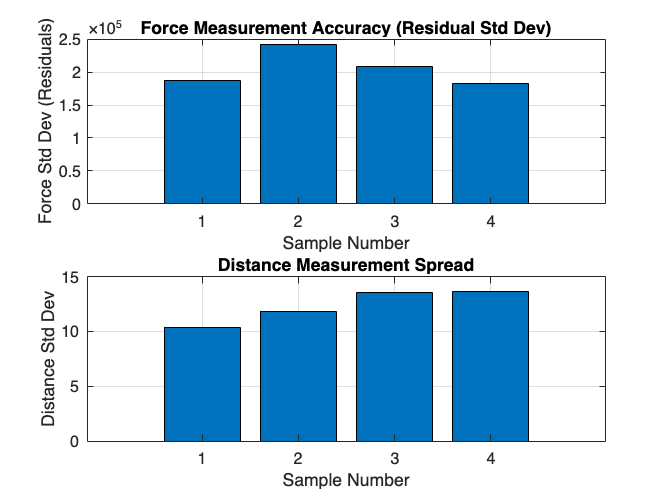


% ---- Plot Results ----

figure;

% Force residual stds per sample
subplot(2,1,1);
bar(allAvgForceStds);
xlabel('Sample Number');
ylabel('Force Std Dev (Residuals)');
title('Force Measurement Accuracy (Residual Std Dev)');
grid on;

% Distance stds per sample
subplot(2,1,2);
bar(allAvgDistanceStds);
xlabel('Sample Number');
ylabel('Distance Std Dev');
title('Distance Measurement Spread');
grid on;